# WPI HPRC Sensor Calibration

Author: Daniel Pearson

Version: 2/11/2024

clear variables; close all; clc;

set(groot, 'DefaultTextInterpreter', 'latex');
set(groot, 'DefaultLegendInterpreter', 'latex');

dt = 0.025; % [s] Board logging at 40Hz
g = 9.80665; % [m/s^2] gravitational acceleration

## Load Data from LOG

xUpData = readtable('X_UP.csv');
% Truncate to 550 Rows of data logger
xUpData = xUpData(1:550,:);
yUpData = readtable('Y_UP.csv');
yUpData = yUpData(1:550,:);
zUpData = readtable('Z_UP.csv');
zUpData = zUpData(1:550,:);

## Accelerometer

### X Acceleration Plot

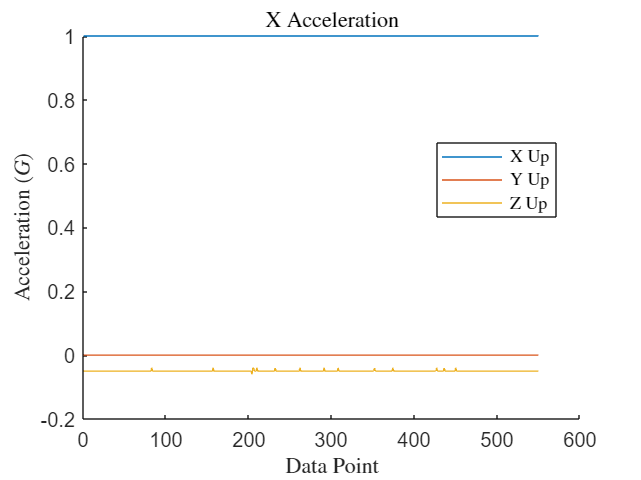

figure();
hold on
plot(xUpData.ACCELX);
plot(yUpData.ACCELX);
plot(zUpData.ACCELX);
hold off;
legend('X Up', 'Y Up', 'Z Up', 'Location','best');
title("X Acceleration");
ylabel("Acceleration $(G)$");
xlabel("Data Point")

### Y Acceleration Plot

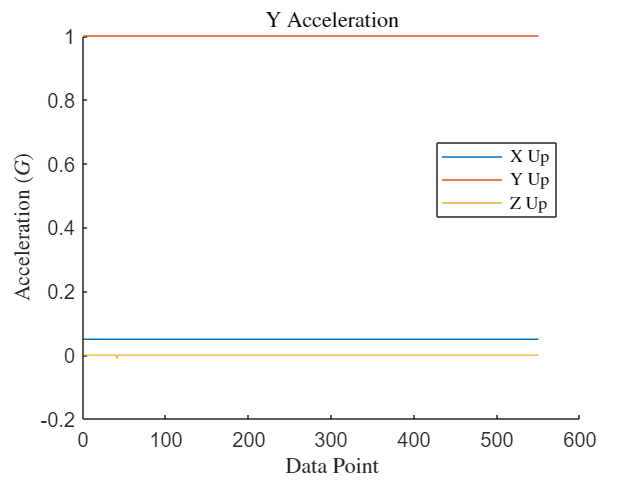

figure();
hold on
plot(xUpData.ACCELY);
plot(yUpData.ACCELY);
plot(zUpData.ACCELY);
hold off;
legend('X Up', 'Y Up', 'Z Up', 'Location','best');
title("Y Acceleration");
ylabel("Acceleration $(G)$");
xlabel("Data Point")

### Z Acceleration Plot

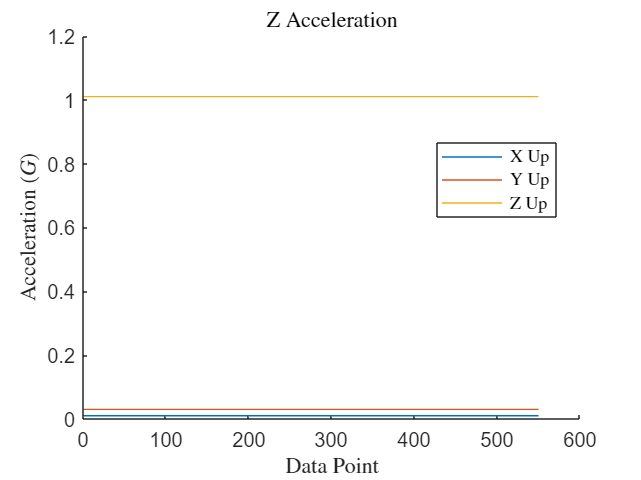

figure();
hold on
plot(xUpData.ACCELZ);
plot(yUpData.ACCELZ);
plot(zUpData.ACCELZ);
hold off;
legend('X Up', 'Y Up', 'Z Up', 'Location','best');
title("Z Acceleration");
ylabel("Acceleration $(G)$");
xlabel("Data Point")

## Gyroscope

### X Angular Velocity Plot

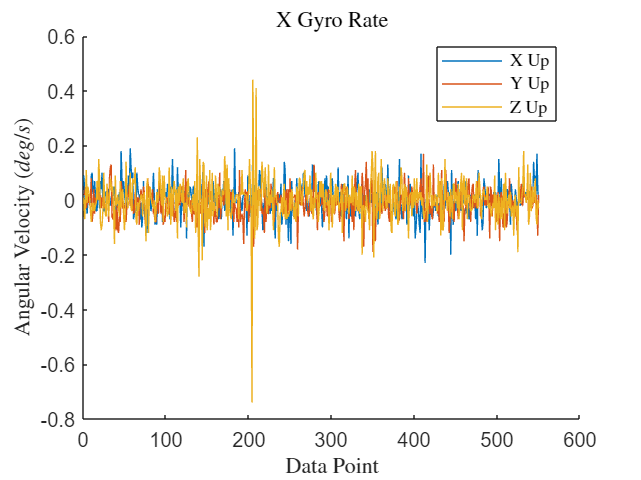

figure();
hold on
plot(xUpData.GYROX);
plot(yUpData.GYROX);
plot(zUpData.GYROX);
hold off;
legend('X Up', 'Y Up', 'Z Up', 'Location','best');
title("X Gyro Rate");
ylabel("Angular Velocity $(deg/s)$");
xlabel("Data Point")

### Y Angular Velocity Plot

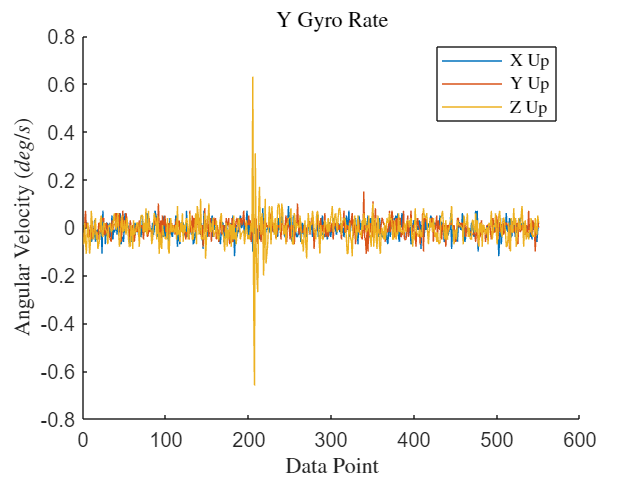

figure();
hold on
plot(xUpData.GYROY);
plot(yUpData.GYROY);
plot(zUpData.GYROY);
hold off;
legend('X Up', 'Y Up', 'Z Up', 'Location','best');
title("Y Gyro Rate");
ylabel("Angular Velocity $(deg/s)$");
xlabel("Data Point")

### Z Angular Velocity Plot

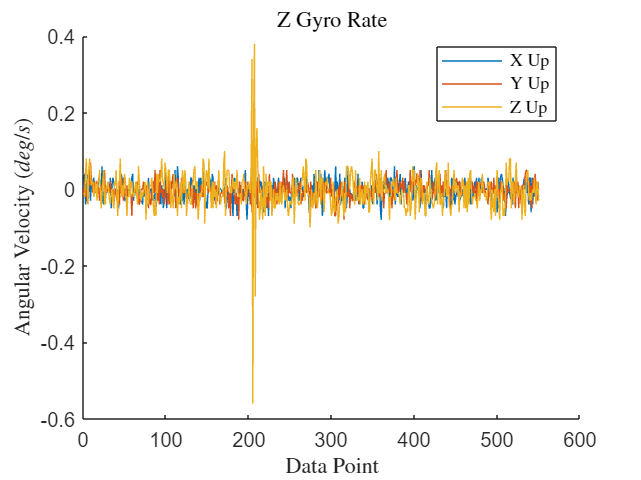

figure();
hold on
plot(xUpData.GYROZ);
plot(yUpData.GYROZ);
plot(zUpData.GYROZ);
hold off;
legend('X Up', 'Y Up', 'Z Up', 'Location','best');
title("Z Gyro Rate");
ylabel("Angular Velocity $(deg/s)$");
xlabel("Data Point")

## Calibration

% Using X Up Data
biasAccX_x = mean(xUpData.ACCELX) - 1

biasAccX_x = 0

biasAccY_x = mean(xUpData.ACCELY)

biasAccY_x = 0.0500

biasAccZ_x = mean(xUpData.ACCELZ)

biasAccZ_x = 0.0100

% Using Y Up Data
biasAccX_y = mean(yUpData.ACCELX)

biasAccX_y = 0

biasAccY_y = mean(yUpData.ACCELY) - 1

biasAccY_y = 0

biasAccZ_y = mean(yUpData.ACCELZ)

biasAccZ_y = 0.0300


% Using X Up Data
biasGyroX_x = mean(xUpData.GYROX)

biasGyroX_x = 0.0017

biasGyroY_x = mean(xUpData.GYROY)

biasGyroY_x = -0.0054

biasGyroZ_x = mean(xUpData.GYROZ)

biasGyroZ_x = -0.0046


% Using Y Up Data
biasGyroX_y = mean(yUpData.GYROX)

biasGyroX_y = -0.0102

biasGyroY_y = mean(yUpData.GYROY)

biasGyroY_y = -0.0014

biasGyroZ_y = mean(yUpData.GYROZ)

biasGyroZ_y = -0.0044